Exercise 2

alpha=2;
m=20;
A = alpha_example(alpha,m);

eigvals = eig(A);

n=100;

[Q,R] = qr(A);
p = [1,2,3,4];

errfun=@(A) max(max(abs(tril(A,-1))))

errfun = function_handle with value:
    @(A)max(max(abs(tril(A,-1))))


ERROR = []


ERROR =

     []



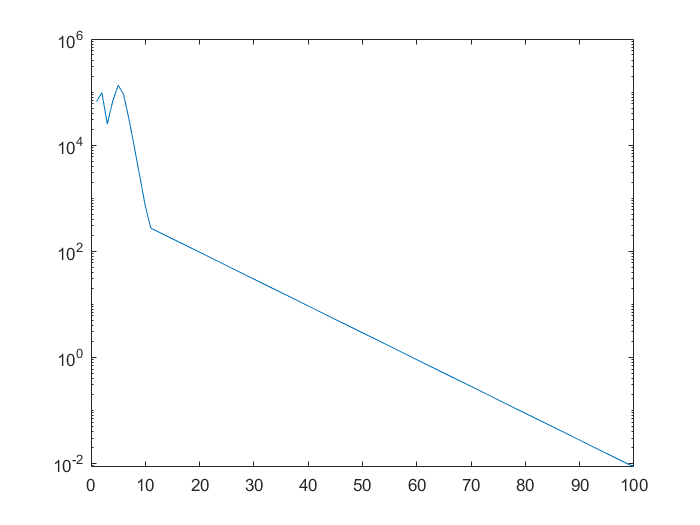


for i=1:n
    [Q,R] = qr(A);
    A = R*Q;
    ERROR = [ERROR; errfun(A)];
end

semilogy(ERROR)


eigvals = sort(abs(eigvals), 'descend')

eigvals = 	1.0e+05 *

    5.2429
    4.6662
    1.3107
    0.6554
    0.3277
    0.1638
    0.0819
    0.0410
    0.0205
    0.0102


QReigval = sort(diag(A), 'descend')

QReigval = 	1.0e+05 *

    5.2429
    4.6662
    1.3107
    0.6554
    0.3277
    0.1638
    0.0819
    0.0410
    0.0205
    0.0102


Exercise 2a)

clc; clear variables;

alpha=2;

m=20;
A = alpha_example(alpha,m);

eigvals = eig(A);
eigvals = sort(eigvals, 'descend')

eigvals = 	1.0e+05 *

    5.2429
    4.6662
    1.3107
    0.6554
    0.3277
    0.1638
    0.0819
    0.0410
    0.0205
    0.0102



pred_quotient = eigvals(2) / eigvals(1)

pred_quotient = 0.8900

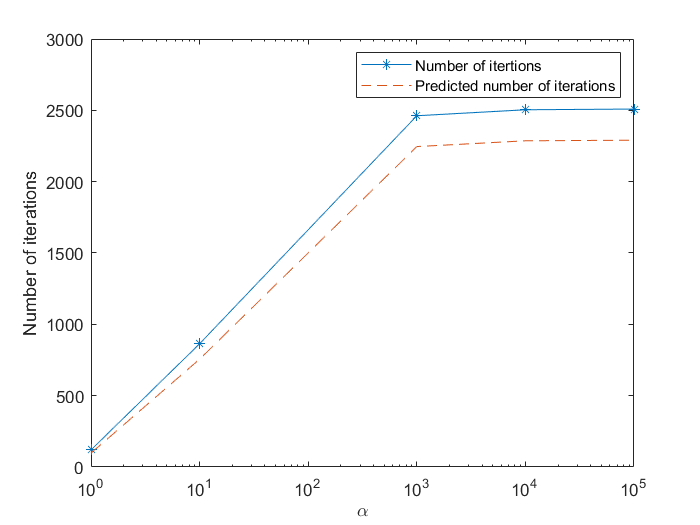


[Q,R] = qr(A);

errfun=@(A) max(max(abs(tril(A,-1))));
ERROR = [];


n=3000;
er = 1;
tol = 10e-10;

alphas = [1, 10, 1e3, 1e4, 1e5];

n_iterations = [];
n_predicted_iterations = [];

for i=1:length(alphas)

    A = alpha_example(alphas(i),m);
    eigvals = eig(A); eigvals = sort(eigvals, 'descend');
    pred_quotient = eigvals(2) / eigvals(1);
    
    j=0; 
    er=1;
    
    while j<n && er > tol
        [Q,R] = qr(A);
        A = R*Q;
        er = errfun(A);
        ERROR = [ERROR; er];
        j=j+1;
    end
    
    if j < n
        n_iterations = [n_iterations ; j];
        n_predicted_iterations = [n_predicted_iterations, log(1e-10)/log(pred_quotient)];
    else
        fprintf("The method has not converged after %d iterations\n", n)
        break
    end
end

semilogx(alphas, n_iterations, "-*");
hold on;
semilogx(alphas, n_predicted_iterations, "--");
xlabel("$\alpha$", "interpreter", "latex")
ylabel("Number of iterations")
legend("Number of itertions", "Predicted number of iterations")

c)

clf

alpha=1e5;
m=20;
A = alpha_example(alpha,m);

eigvals = eig(A);
eigvals = sort(eigvals, 'descend');

n=10000;
[Q,R] = qr(A);
p = [1,2,3,4];

errfun=@(A) max(max(abs(tril(A,-1))))

errfun = function_handle with value:
    @(A)max(max(abs(tril(A,-1))))


ERROR = []


ERROR =

     []




for i=1:n
    [Q,R] = qr(A);
    A = R*Q;
    ERROR = [ERROR; errfun(A)];
end

figure(1)

logerror = log(ERROR);
ns = 1:n;

cut_from = 1000;
ns_cut = ns(cut_from:end)';
X = [ones(length(ns_cut),1) ns_cut]

X =            1        1000
           1        1001
           1        1002
           1        1003
           1        1004
           1        1005
           1        1006
           1        1007
           1        1008
           1        1009



b = X \ logerror(cut_from:end);
quot = exp(b(2))

quot = 0.9900

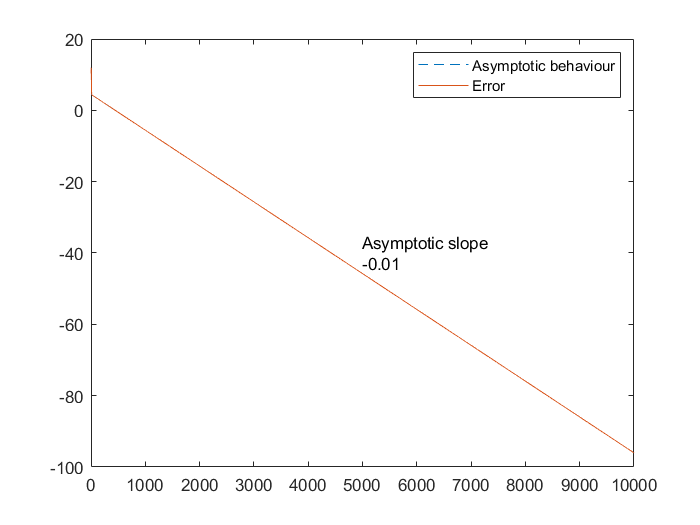

plot(ns, b(1) + b(2)*ns, "--");
hold on;
plot(ns, logerror)
txt = {"Asymptotic slope", round(b(2),2)};
text(5000, -40, txt);
legend("Asymptotic behaviour", "Error")


clf 

figure(2)
clf
semilogy(ns(cut_from: end), ERROR(cut_from:end));
pred = exp(b(1)+b(2)*ns)

pred =    88.2641   87.3813   86.5073   85.6420   84.7854   83.9374   83.0979   82.2667   81.4439   80.6293   79.8228   79.0245   78.2341   77.4516   76.6769   75.9100   75.1507   74.3991   73.6549   72.9182   72.1889   71.4669   70.7521   70.0444   69.3438   68.6502   67.9636   67.2838   66.6108   65.9446   65.2850   64.6320   63.9856   63.3456   62.7120   62.0848   61.4638   60.8490   60.2404   59.6379   59.0414   58.4509   57.8663   57.2875   56.7145   56.1472   55.5856   55.0297   54.4793   53.9344


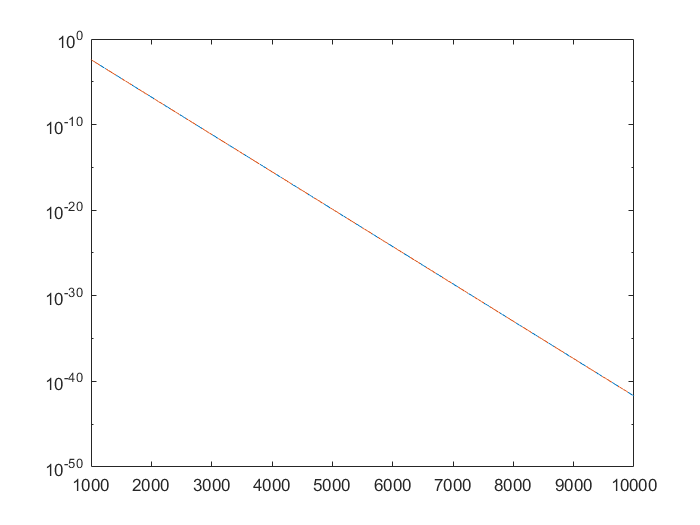

hold on;
semilogy(ns(cut_from:end), pred(cut_from:end), "--")

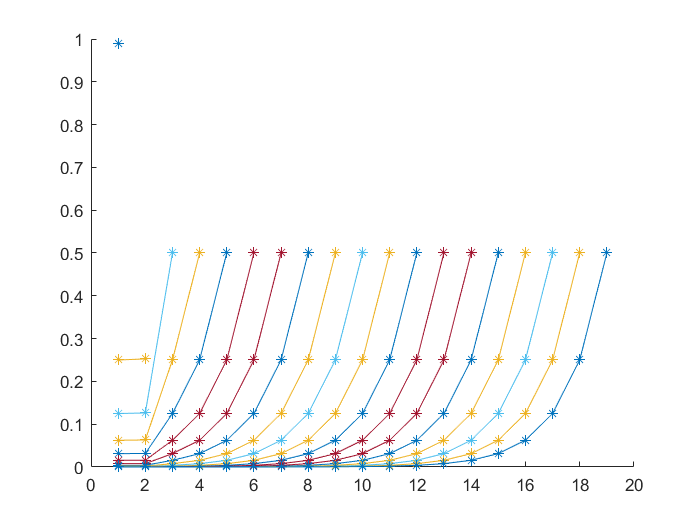



eigvals = sort(eigvals, 'descend');
QReigval = sort(diag(A), 'descend');

figure(3);

hold on

for i=1:length(eigvals)
    eig_i = eigvals(i)*ones(i-1);
    plot(eig_i ./ eigvals(1:i-1), "-*")
end

It would be dominated by the max value of lambda_i / lambda_j (restricted to j>i), which is i=1, j=2